# Assignment M4.2 Solution

## Problem M1

Determine the positive real root of $\ln \left(x^2 \right)-0\ldotp 7=0$ by 

1) graphically by plotting the function, 

(2) using fzero() in the  interval [0.5, 2] and error tolerance of 1e-5.

%M1 solution
f = @(x) log(x.*x) - 0.7

f = function_handle with value:
    @(x)log(x.*x)-0.7


bounds = [0.5, 2]

bounds =     0.5000    2.0000


epsilon = 1e-5

epsilon = 1.0000e-05

options = optimset('TolX', epsilon)

options = struct with fields:
                   Display: []
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: []
                      TolX: 1.0000e-05
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: []
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                LargeScale: []
 

fzero(f, bounds, options)

ans = 1.4191


x = linspace(0.5, 2, 100)

x =     0.5000    0.5152    0.5303    0.5455    0.5606    0.5758    0.5909    0.6061    0.6212    0.6364    0.6515    0.6667    0.6818    0.6970    0.7121    0.7273    0.7424    0.7576    0.7727    0.7879    0.8030    0.8182    0.8333    0.8485    0.8636    0.8788    0.8939    0.9091    0.9242    0.9394    0.9545    0.9697    0.9848    1.0000    1.0152    1.0303    1.0455    1.0606    1.0758    1.0909    1.1061    1.1212    1.1364    1.1515    1.1667    1.1818    1.1970    1.2121    1.2273    1.2424


y = f(x)

y =    -2.0863   -2.0266   -1.9686   -1.9123   -1.8575   -1.8041   -1.7522   -1.7016   -1.6522   -1.6040   -1.5569   -1.5109   -1.4660   -1.4220   -1.3790   -1.3369   -1.2957   -1.2553   -1.2157   -1.1768   -1.1387   -1.1013   -1.0646   -1.0286   -0.9932   -0.9584   -0.9242   -0.8906   -0.8576   -0.8250   -0.7930   -0.7615   -0.7305   -0.7000   -0.6699   -0.6403   -0.6111   -0.5823   -0.5539   -0.5260   -0.4984   -0.4712   -0.4443   -0.4178   -0.3917   -0.3659   -0.3404   -0.3153   -0.2904   -0.2659



plot(x, y, 'b-')
yline(0, 'r--')
xline(1.4191, 'r--')


## Problem M2

`Consider the function `$x^3 -6x^2 +11x-6\ldotp 1=0$ 

`1) Use fzero() to find a root of this function with initial guess of x=3 and error tolerance of 1e-7. `

`2) Use roots to find all the roots of the function.`

%M2 solution
f = @(x) x.^3 - 6.*x.^2 + 11.*x - 6.1

f = function_handle with value:
    @(x)x.^3-6.*x.^2+11.*x-6.1


x0 = 3

x0 = 3

epsilon = 1e-7

epsilon = 1.0000e-07

options = optimset('TolX', epsilon)

options = struct with fields:
                   Display: []
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: []
                      TolX: 1.0000e-07
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: []
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                LargeScale: []
 

fzero(f, x0, options)

ans = 3.0467


r = roots([1, -6, 11, -6.1])

r =     3.0467
    1.8990
    1.0544


## Problem M3

`Figure below shows a uniform beam subject to a linearly increasing distributed load. The equation for the resulting elastic curve (y in cm) vs. length (x in cm) is`


$$y={w_{0} \over 120\,E\,I\,L} (-x^{5}+2L^{2}x^{3}-L^{4}x)$$


`where `$$L = 600\,cm$, $E = 50000\,\rm{kN/cm^{2}}$, $I = 30000\, \rm{cm^{4}}$, and $w_{0} = 2.5\,kN/cm$.
$

`1. ``Determine the approximate point of maximum deflection (i.e., minimum of y) graphically by plotting this function.`

`2. ``Use the direct (non-gradient) method to determine the point of maximum deflection (minimum of y) and the maximum defelction value (in cm). This is done by using the ```fminsearch``` function until the approximate error falls below `$\epsilon_{s} = 1e-6$` with initial guesses of `$$x_0 = \frac{L}{2}$$`. Compare your predictions with that of Parts (1).`

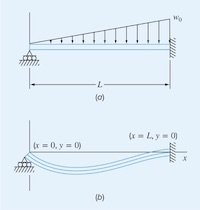

%M3 Solution
w0 = 2.5

w0 = 2.5000

L = 600

L = 600

E=50000

E = 50000

I=30000

I = 30000


y_f = @(x) w0/(120*E*I*L)*(-x.^5+2*L^2.*x.^3-L^4.*x)

y_f = function_handle with value:
    @(x)w0/(120*E*I*L)*(-x.^5+2*L^2.*x.^3-L^4.*x)



x = linspace(0, L, 100)

x =          0    6.0606   12.1212   18.1818   24.2424   30.3030   36.3636   42.4242   48.4848   54.5455   60.6061   66.6667   72.7273   78.7879   84.8485   90.9091   96.9697  103.0303  109.0909  115.1515  121.2121  127.2727  133.3333  139.3939  145.4545  151.5152  157.5758  163.6364  169.6970  175.7576  181.8182  187.8788  193.9394  200.0000  206.0606  212.1212  218.1818  224.2424  230.3030  236.3636  242.4242  248.4848  254.5455  260.6061  266.6667  272.7273  278.7879  284.8485  290.9091  296.9697


y = y_f(x)

y =          0   -0.0182   -0.0363   -0.0544   -0.0725   -0.0904   -0.1083   -0.1260   -0.1436   -0.1609   -0.1781   -0.1951   -0.2118   -0.2283   -0.2445   -0.2603   -0.2759   -0.2911   -0.3060   -0.3205   -0.3346   -0.3482   -0.3615   -0.3743   -0.3866   -0.3984   -0.4098   -0.4206   -0.4309   -0.4407   -0.4499   -0.4585   -0.4666   -0.4741   -0.4810   -0.4872   -0.4929   -0.4979   -0.5023   -0.5061   -0.5092   -0.5117   -0.5135   -0.5147   -0.5152   -0.5150   -0.5142   -0.5128   -0.5106   -0.5079


plot(x, y, 'g-')

x0 = L/2

x0 = 300

epsilon = 1e-6

epsilon = 1.0000e-06

options = optimset('TolX', epsilon)

options = struct with fields:
                   Display: []
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: []
                      TolX: 1.0000e-06
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: []
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                LargeScale: []
 

fminsearch(y_f, x0, options)

ans = 268.3282